mu1 = [3, 4]

mu1 =      3     4


mu2 = [9, 8]

mu2 =      9     8


sigma1 = [1, 0.5; 0.5, 1];
sigma2 = [1, -0.2; -0.2, 1];
phi = [0.3, 0.7]

phi =    0.300000000000000   0.700000000000000


N = 1000

N =         1000



%mu1 = [0,0];
%mu2 = [3, 0];
%phi = [0.3, 0.7];


[m, s, p,X] = EMAlgo(mu1, mu2, sigma1, sigma2, N, phi);

m

m =    3.014988745886342   4.048095731814608
   8.949519355014255   8.024465895118048


s{1}

ans =    1.063189933781192   0.616866082457083
   0.616866082457083   1.264991712110986


s{2}

ans =    0.989152575884177  -0.199923834991369
  -0.199923834991369   0.961962006477779


p

p =    0.281046630880215   0.718953369119784


X

X =   10.833885014595086   5.420014110462416
   9.318765239858982   6.654979324605253
   3.342624466538650   7.270294887896326
   7.650113059843479  11.243582948396043
   8.936945126810343   8.712913139297566
   2.875855651783688   5.228043798190964
  10.417192413429614   8.374491653746597
   3.717238651328838   5.770444500226945
  10.034693009917859   8.505260469377957
   9.293871467096658   7.169849245590123
   7.852929893030850   7.182139131935211
   0.055715838005104   3.773531792883326
   8.245071680830296   9.493598551239550
   2.897757553914509   3.739779505256684
   9.312858596637428   7.090022486182347
   8.835120980790961   8.648000828750554
  10.109273297614397   6.931941848962280
   9.600704319018829   6.690272238246562
   2.993150671896652   5.323872117532895
   9.371378812760058   7.704697565649866
   7.910935704947764   8.249712528819700
  10.100610217880867   9.292890435912106
   7.508409689362391   7.571013767560672
   5.350457224002042   4.642101744033194
   8.8075814


% Probability density of mixture: 
p_initial = @(x) phi(1) * mvnpdf(x, mu1, sigma1) + ...
    phi(2) * mvnpdf(x, mu2, sigma2) 

p_initial = function_handle with value:
    @(x)phi(1)*mvnpdf(x,mu1,sigma1)+phi(2)*mvnpdf(x,mu2,sigma2)



p_new = @(x) p(1) * mvnpdf(x, m(1,:), s{1}) + ...
    p(2) * mvnpdf(x, m(2,:), s{2}) 

p_new = function_handle with value:
    @(x)p(1)*mvnpdf(x,m(1,:),s{1})+p(2)*mvnpdf(x,m(2,:),s{2})



% Step 1: first plot original parameters with the sampled
% X data

% Sampled data using Scatter plot
figure(1);

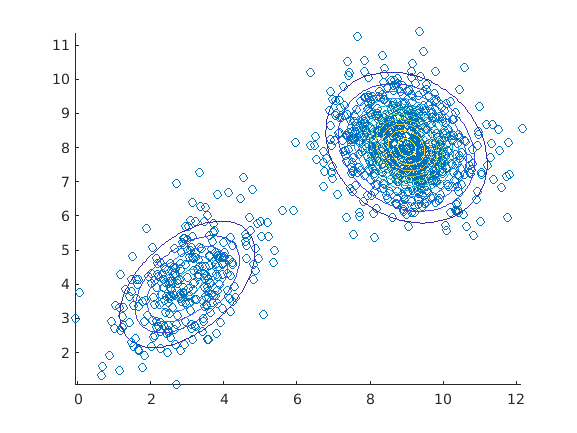

clf; 
X1 = X(:, 1);
X2 = X(:, 2);
scatter(X1, X2) % the two dimensions sampled from data

hold on; 


% Deterministic part: mixture function Contour plot : 

% making the grid of values
x1 = linspace(min(X1), max(X1));     % 1 x 100
x2 = linspace(min(X2), max(X2));     % 1 x 100

% joining xx2 on the right of xx1
[xx1 xx2] = meshgrid(x1, x2);        % xx1 is 100 x 100

% get the values from the multivariate pdf using
% the meshgrid
f = p_initial([xx1(:), xx2(:)]);
% size(xx1(:)) = 10000 x 1
% size([xx1(:), xx2(:)]) = 10000 x 2
% size(f) = 10000 x 1

% contour plot 
% note: must reshape f to be 100x100 since both the 
% xx1 and xx2 are 100 x 100. 
contour(xx1, xx2, ...
    reshape(f, 100, 100))

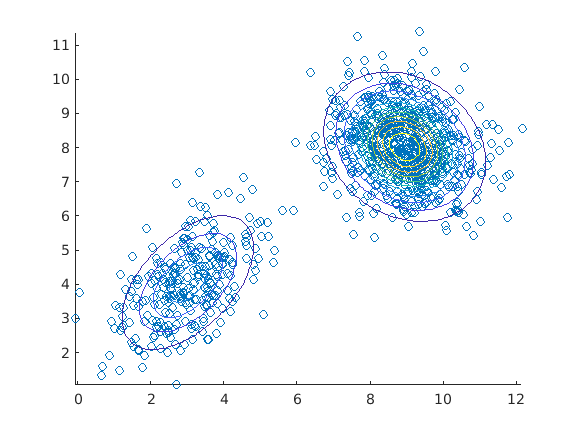

% Step 2: plot the estimated parameters with the sampled
% X data. 


% Sampled data using Scatter plot
figure(1);
clf; 
X1 = X(:, 1);
X2 = X(:, 2);
scatter(X1, X2) % the two dimensions sampled from data

hold on; 


% Deterministic part: mixture function Contour plot 
% % USING NEW ESTIMATED PARAMETERS: 

% making the grid of values
x1 = linspace(min(X1), max(X1));     % 1 x 100
x2 = linspace(min(X2), max(X2));     % 1 x 100

% joining xx2 on the right of xx1
[xx1 xx2] = meshgrid(x1, x2);        % xx1 is 100 x 100

% get the values from the multivariate pdf using
% the meshgrid
f = p_new([xx1(:), xx2(:)]);
% size(xx1(:)) = 10000 x 1
% size([xx1(:), xx2(:)]) = 10000 x 2
% size(f) = 10000 x 1

% contour plot 
% note: must reshape f to be 100x100 since both the 
% xx1 and xx2 are 100 x 100. 
contour(xx1, xx2, ...
    reshape(f, 100, 100))


% Compare original vs estimated parameters in a table

% Means comparison
table(mu1', m(1,:)', mu2', m(2,:)', 'VariableNames', {'GivenMu1', 'EstMu1', 'GivenMu2', 'EstMu2'})

ans = 2×4 table
    GivenMu1         EstMu1         GivenMu2         EstMu2     
    ________    ________________    ________    ________________

    3           3.01498874588634    9           8.94951935501425
    4           4.04809573181461    8           8.02446589511805



% Sigma comparison
table(sigma1, s{1}, 'VariableNames', {'GivenSigma1', 'EstSigma1'})

ans = 2×2 table
    GivenSigma1                  EstSigma1               
    ___________    ______________________________________

      1    0.5      1.06318993378119    0.616866082457083
    0.5      1     0.616866082457083     1.26499171211099



table(sigma2, s{2}, 'VariableNames', {'GivenSigma2', 'EstSigma2'})

ans = 2×2 table
    GivenSigma2                    EstSigma2                
    ____________    ________________________________________

       1    -0.2     0.989152575884177    -0.199923834991369
    -0.2       1    -0.199923834991369     0.961962006477779


 % Prior prob comparison
 table(phi', p', 'VariableNames', {'GivenPrior', 'EstPrior'})

ans = 2×2 table
    GivenPrior        EstPrior     
    __________    _________________

    0.3           0.281046630880215
    0.7           0.718953369119784
